# CNN Spectrogram Algorithm

## Adapted from MATLAB example: Transfer Learning Using Pretrained Network

This example shows how to fine-tune a pretrained GoogLeNet convolutional neural network to perform classification on a new collection of images.

GoogLeNet has been trained on over a million images and can classify images into 1000 object categories (such as keyboard, coffee mug, pencil, and many animals). The network has learned rich feature representations for a wide range of images. The network takes an image as input and outputs a label for the object in the image together with the probabilities for each of the object categories.

Transfer learning is commonly used in deep learning applications. You can take a pretrained network and use it as a starting point to learn a new task. Fine-tuning a network with transfer learning is usually much faster and easier than training a network with randomly initialized weights from scratch. You can quickly transfer learned features to a new task using a smaller number of training images.

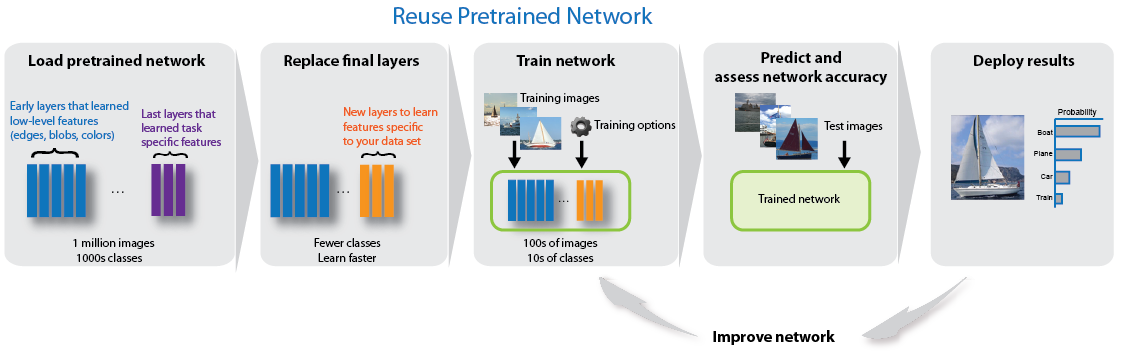

wd = '~/Documents/GitHub/CNN_Spectrogram_Algorithm/Demo-Training/';
imdsTrain = imageDatastore([wd 'train'] ...
    , 'IncludeSubfolders', true ...
    , 'LabelSource','foldernames' ...
    );
imdsValidate = imageDatastore([wd 'valid'] ...
    , 'IncludeSubfolders', true ...
    , 'LabelSource','foldernames' ...
    );

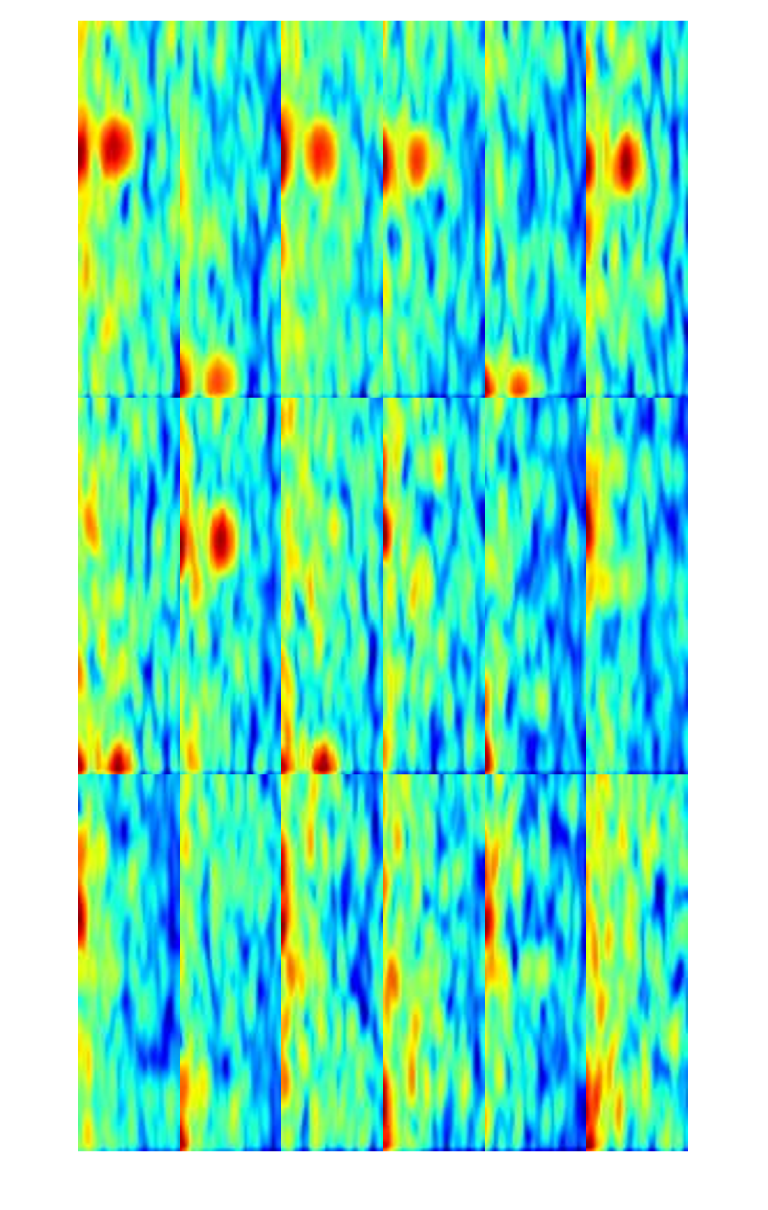

% Look at a few examples of the training spectrograms
montage(imdsTrain.Files( ...
    [find(imdsTrain.Labels == "Yes", 9); ...
    find(imdsTrain.Labels == "No", 9)]) ...
    , "size", [3, 6]);

## Load Pretrained Network

Load the pretrained GoogLeNet neural network. If Deep Learning Toolbox™ Model *for GoogLeNet Network* is not installed, then the software provides a download link.

net = googlenet;

Use `deepNetworkDesigner` to display an interactive visualization of the network architecture and detailed information about the network layers.

deepNetworkDesigner(net)

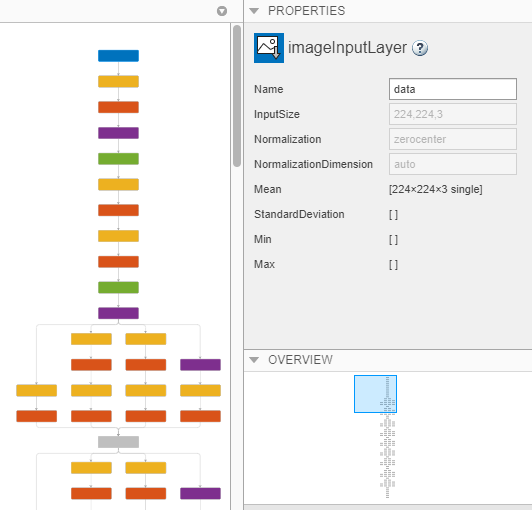

The first layer, which is the image input layer, requires input images of size 224-by-224-by-3, where 3 is the number of color channels. 

inputSize = net.Layers(1).InputSize

inputSize =    224   224     3


## Replace Final Layers

The fully connected layer and classification layer of the pretrained network `net` are configured for 1000 classes. These two layers, `loss3-classifier` and `output` in GoogLeNet, contain information on how to combine the features that the network extracts into class probabilities, a loss value, and predicted labels. To retrain a pretrained network to classify new images, replace these two layers with new layers adapted to the new data set.

Extract the layer graph from the trained network.

lgraph = layerGraph(net); 

Replace the fully connected layer with a new fully connected layer that has number of outputs equal to the number of classes. To make learning faster in the new layers than in the transferred layers, increase the `WeightLearnRateFactor` and `BiasLearnRateFactor` values of the fully connected layer.

numClasses = numel(categories(imdsTrain.Labels))

numClasses = 2

newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...  % these are from the matlab example
    'BiasLearnRateFactor',10);
    
lgraph = replaceLayer(lgraph,'loss3-classifier',newLearnableLayer);

The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time.

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

## Train Network

The network requires input images of size 224-by-224-by-3, but the images in the image datastores have different sizes. Use an augmented image datastore to automatically resize the training images. Specify additional augmentation operations to perform on the training images: randomly flip the training images along the vertical axis, and randomly translate them up to 30 pixels horizontally and vertically. Data augmentation helps prevent the network from overfitting and memorizing the exact details of the training images.  

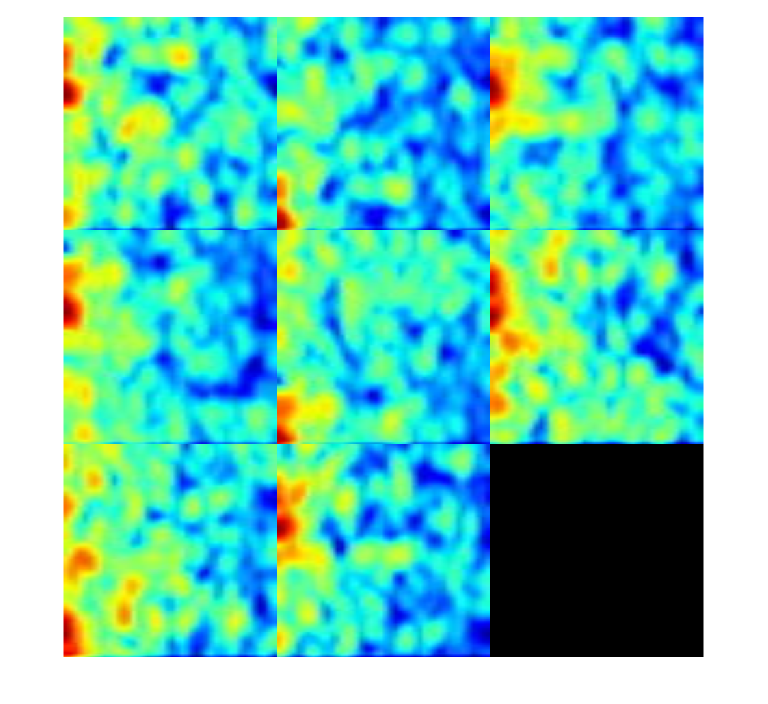

% This augmentation doesn't make sense for our spectrograms
pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    ...'RandXReflection',true, ...
    ...'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore( ...
    inputSize(1:2),imdsTrain ...
    , "OutputSizeMode", "resize" ...
    ..., 'DataAugmentation',imageAugmenter ...
    );

montage(augimdsTrain.preview.input)

To automatically resize the validation images without performing further data augmentation, use an augmented image datastore without specifying any additional preprocessing operations.

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidate);

Specify the training options. For transfer learning, keep the features from the early layers of the pretrained network (the transferred layer weights). To slow down learning in the transferred layers, set the initial learning rate to a small value. In the previous step, you increased the learning rate factors for the fully connected layer to speed up learning in the new final layers. This combination of learning rate settings results in fast learning only in the new layers and slower learning in the other layers. When performing transfer learning, you do not need to train for as many epochs. An epoch is a full training cycle on the entire training data set. Specify the mini-batch size and validation data. The software validates the network every `ValidationFrequency` iterations during training.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress' ...
    );

Train the network consisting of the transferred and new layers. By default, `trainNetwork` uses a GPU if one is available. This requires Parallel Computing Toolbox™ and a supported GPU device. For information on supported devices, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, it uses a CPU. You can also specify the execution environment by using the `'ExecutionEnvironment'` name-value pair argument of `trainingOptions`.

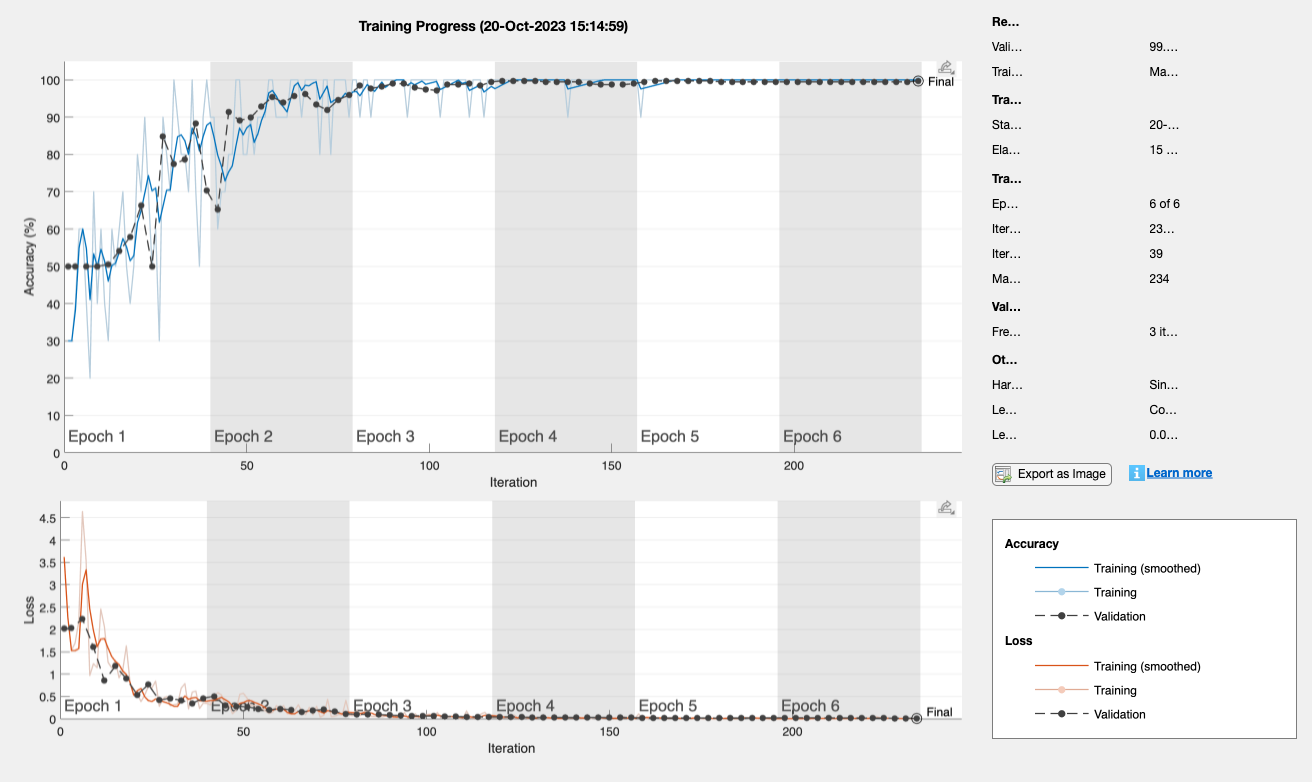

netTransfer = trainNetwork(augimdsTrain,lgraph,options);

## On my laptop, it took 15 minutes to fine tune GoogleNet

## 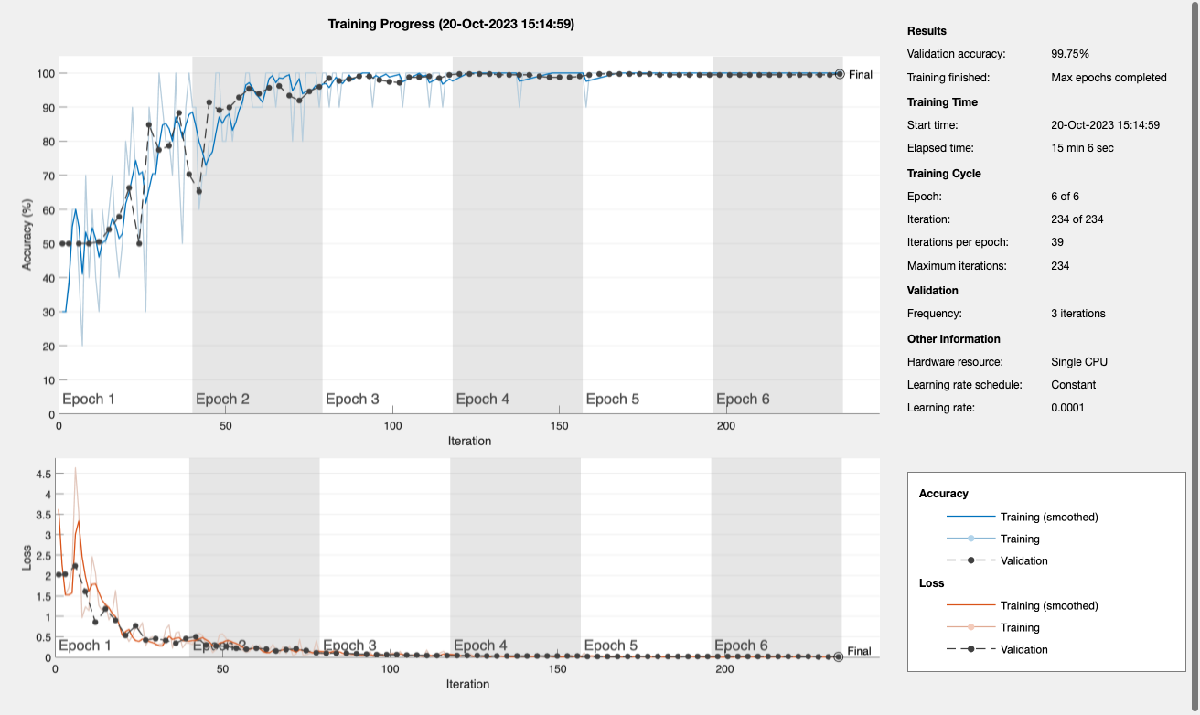

net = resnet;